# Setup

clear;
filename = "focus_scan_zigzag.csv"

filename = "focus_scan_zigzag.csv"

scans_data = readtable(filename)

scans_data = 196×92 table
     Var1       Var2       Var3       Var4      Var5       Var6       Var7       Var8       Var9      Var10      Var11      Var12      Var13      Var14      Var15      Var16      Var17      Var18      Var19      Var20      Var21      Var22     Var23      Var24      Var25      Var26      Var27      Var28      Var29      Var30      Var31      Var32      Var33      Var34      Var35


angles = scans_data{1, :}

angles =   -18.9844  -18.6328  -18.2812  -17.9297  -17.5781  -17.2266  -16.8750  -16.5234  -16.1719  -15.8203  -15.4687  -15.1172  -14.7656  -14.4141  -14.0625  -13.7109  -13.3594  -13.0078  -12.6562  -12.3047  -11.9531  -11.6016  -11.2500  -10.8984  -10.5469  -10.1953   -9.8437   -9.4922   -9.1406   -8.7891   -8.4375   -8.0859   -7.7344   -7.3828   -7.0312   -6.6797   -6.3281   -5.9766   -5.6250   -5.2734   -4.9219   -4.5703   -4.2187   -3.8672   -3.5156   -3.1641   -2.8125   -2.4609   -2.1094   -1.7578


total_frame = size(scans_data,1)

total_frame = 196

data_point = size(angles,2)

data_point = 92


% Plotting Colors
ax = gca;

function savgol_filter = SalGov(data_file,frame,poly,win)
    scans_data = readtable(data_file);
    scan = scans_data{frame, :};
    savgol_filter = sgolayfilt(scan, poly, win);
end

disp("Setup Complete.")

Setup Complete.


# **Savitzky–Golay Filtering**

**Key parameters**

`poly`** (polynomial order)**

- What: Order of the local polynomial fitted within each window.

- Use: 2–3 for most sensor signals; higher tracks curvature more but can overfit noise.

- Constraints: `poly < win` and typically `poly ≥ 2`.

`win`** (window length, ****must be odd****)**

- What: Number of samples in each local fit.

- Use: Start at 7–15 for typical LiDAR scan smoothing; larger → smoother but can blur narrow features.

- Constraints: odd number; `win ≥ poly + 2`; `win ≤ length(signal)`.

**When to tweak**

- Increase `win` if the curve is still jagged (noisy).

- Decrease `win` if peaks/valleys look flattened or shifted.

- Try `poly=2` first; raise to **3** only if you need slightly better curvature preservation.

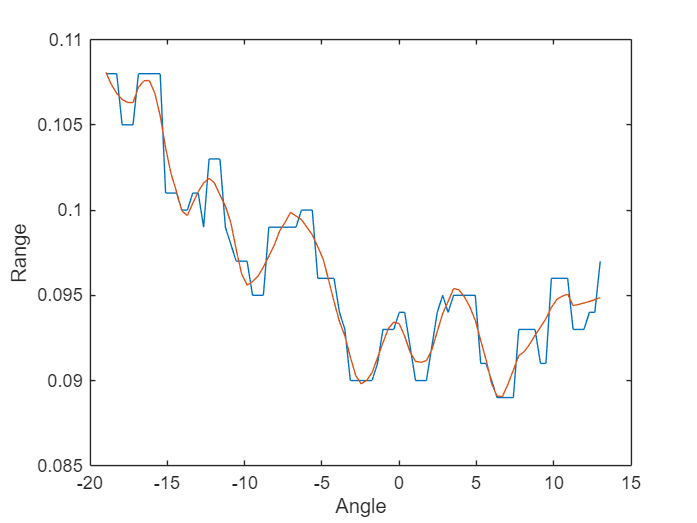

scan_index = randi([1,total_frame]); % Random Frame
scan = scans_data{scan_index, :};

% Poly = 2  Win = 11
filter_data = SalGov(filename, scan_index, 2, 11);

% Plot
figure()
plot(angles, scan);
xlabel('Angle'); ylabel('Range'); 
hold on
plot(angles, filter_data);
hold off

# findpeaks()

### What it does

    Detects **local ****maxima** in a vector. To find **valleys**, run it on the **negative** of your signal.

**    Maxima** = You have to flip your signal (Our weld is Minima)

### **Value parameters**

`'MinPeakProminence', P`

- What: How much a peak stands out from its surroundings (baseline-to-peak).

- Effect: Bigger P = fewer, stronger peaks. Best first knob to turn.

`'MinPeakDistance', D`

- What: Minimum separation between peaks (in samples or x-units if you pass `x`).

- Use: Prevents multiple detections inside one broad feature.

`'MinPeakHeight', H`

- What: Absolute amplitude threshold for peaks.

- Use: Useful if you know noise floor / absolute scale.

`'MinPeakWidth', W`** and **`'MaxPeakWidth', Wmax`

- What: Lower/upper bounds on peak width (in samples or x-units).

- Use: Filter out spikes (too narrow) or trends (too wide).

`'Threshold', T`

- What: Minimum vertical drop around a peak.

- Use: Less common than Prominence; can help with uniform noise.

`'NPeaks', N`

- What: Return at most N strongest peaks (by prominence).

`'SortStr','descend'|'ascend'`

- What: Order peaks by prominence.

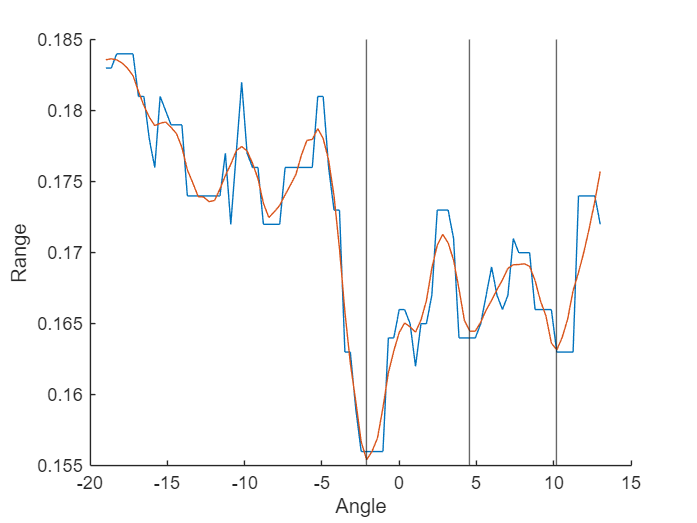


scan_index = randi([1,total_frame]); % Random Frame
scan = scans_data{scan_index, :};

filter_data = SalGov(filename, scan_index, 2, 11);
[pksN, locs] = findpeaks(-filter_data, angles, ...
    'MinPeakProminence', 0.001, 'SortStr','descend', 'NPeaks', 3);

figure()
hold on

plot(angles, scan,'DisplayName','Raw Scan');
plot(angles, filter_data,'DisplayName','Filtered');

% If there is peaks exist.
if isempty(locs) == false
    xline(locs);
end

xlabel('Angle'); ylabel('Range'); 
hold off